if ismac
    % Code to run on Mac platform
    datapath="/Users/studio/Documents/MatlabData"
elseif isunix
    % Code to run on Linux platform
    homedir = '/home/ganesh/GoogleDrive/MATLAB';
    audiodir = append(homedir,"/Audio");
    cd(audiodir);
    currentFolder = pwd
    datapath="/home/ganesh/matlab_r2021b/data_is_here/RagaID";
elseif ispc
    % Code to run on Windows platform
    homedir = fullfile('G:','My Drive','MATLAB')
    audiodir = fullfile(homedir,'Audio')
    cd(audiodir)
    currentFolder = pwd
    datapath="D:\MatlabData"
else
    disp('Platform not supported')
end

homedir = 'G:\My Drive\MATLAB'

audiodir = 'G:\My Drive\MATLAB\Audio'

currentFolder = 'G:\My Drive\MATLAB\Audio'

datapath = "D:\MatlabData"


segmentDuration = 4; %4 second audio .wav file 
frameDuration = 0.025; %duration of hanning/hamming window
hopDuration = 0.010; %see diagram below
numBands = 32; %number of mel filer banks, i think..

% create AudioDatastore
ADS = audioDatastore(datapath,"IncludeSubfolders",true,"LabelSource","Foldernames")

ADS =   audioDatastore with properties:

                       Files: {
                              'D:\MatlabData\Abhogi\Abhogi_10.wav';
                              'D:\MatlabData\Abhogi\Abhogi_100.wav';
                              'D:\MatlabData\Abhogi\Abhogi_101.wav'
                               ... and 1437 more
                              }
                     Folders: {
                              'D:\MatlabData'
                              }
                      Labels: [Abhogi; Abhogi; Abhogi ... and 1437 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


shuffledADS = shuffle(ADS)

shuffledADS =   audioDatastore with properties:

                       Files: {
                              'D:\MatlabData\Abhogi\Abhogi_648.wav';
                              'D:\MatlabData\Abhogi\Abhogi_506.wav';
                              'D:\MatlabData\Abhogi\Abhogi_21.wav'
                               ... and 1437 more
                              }
                     Folders: {
                              'D:\MatlabData'
                              }
                      Labels: [Abhogi; Abhogi; Abhogi ... and 1437 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


if ~isempty(ver('parallel'))
    pool = gcp;
    numPar = numpartitions(ADS,pool)
else
    numPar = 1
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


numPar = 18

**split ADS to training, validation and test data sets**

[trainADS,valADS,testADS] = splitEachLabel(shuffledADS,0.7,0.2,'randomized');



## create MelSpectrogram with transform on train, val datasets

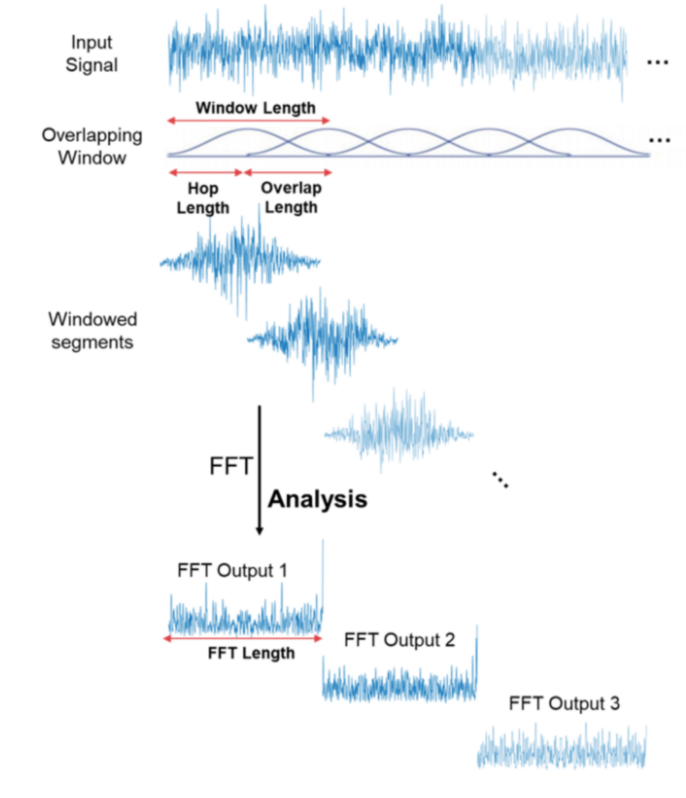

trainADS.reset;valADS.reset;testADS.reset;

ADSnew = transform(trainADS,@extractMelSpectrogram,'IncludeInfo',true)

ADSnew =   TransformedDatastore with properties:

      UnderlyingDatastores: {audioDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@extractMelSpectrogram}
               IncludeInfo: 1


for i = 1:1
    [melSpec,info] = read(ADSnew)
    
    figure(i)
    surf(info.TimeInstants,info.CenterFrequencies,melSpec(:,:,1),'EdgeColor','none');
    xlabel('Time (s)')
    ylabel('Frequency (Hz)')
    [~,name] = fileparts(info.FileName);
    title(name)
    axis([0 info.TimeInstants(end) info.CenterFrequencies(1) info.CenterFrequencies(end)])
    view([0,90])
end

Error using matlab.io.datastore.TransformedDatastore/read (line 222)
Invalid transform function defined on datastore.

Caused by:
    Undefined function 'Spectrogram' for input arguments of type 'double'.

fprintf('----- Extracting XTrain MelSpecs.\n');

----- Extracting XTrain MelSpecs.


XTrain = getMelSpectrogram(trainADS,segmentDuration,frameDuration,hopDuration,numBands,numPar);
XTrain = log10(XTrain + eps);
[numBands,numHops,numChannels,numSpec] = size(XTrain)

numBands = 32

numHops = 398

numChannels = 1

numSpec = 1008

function [dataOut,infoOut] = extractMelSpectrogram(audioIn,info)

    [S,F,T] = Spectrogram(audioIn,info.SampleRate);
    
    dataOut = 10*log10(S+eps);
    infoOut = info;
    infoOut.CenterFrequencies = F;
    infoOut.TimeInstants = T;
end

## FUNCTIONS

function XOutC = getMelSpectrogram(audioIn_ds,segmentDuration,frameDuration,hopDuration,numBands,numPar)
% Mel spectrogram, returned as a column vector, matrix, or 3-D array. 
% The dimensions of S are L-by-M-by-N, where:
% L is the number of frequency bins in each mel spectrum. 
% NumBands and fs determine L.
% M is the number of frames the audio signal is partitioned into. 
% size(audioIn,1), WindowLength, and OverlapLength determine M.
% N is the number of channels such that N = size(audioIn,2)
%Trailing singleton dimensions are removed from the output S.

    % disp("Computing mel spec with padding..");
    numFiles = length(audioIn_ds.Files);
    numHops = ceil((segmentDuration-frameDuration)/hopDuration);
    %numHops =343;
    XOutC = zeros([numBands,numHops,1,numFiles],'single');
parfor ii = 1:numPar
    %fprintf("numPar # : %d \n",ii)
    subds = partition(audioIn_ds,numPar,ii);
    
    XOut = zeros([numBands,numHops,1,numel(subds.Files)],'single');
    A = size(XOut);
    for i = 1:length(subds.Files)
        %fprintf("subds # : %d \n",i)
        [x, info] = read(audioIn_ds);
        x = x(:,1);
        fs = info.SampleRate;
        segmentSamples = round(segmentDuration*fs); %# of samples in full clip
        frameSamples   = round(frameDuration*fs); % # of samples in window length. here is 1102,close to 1024
        hopSamples     = round(hopDuration*fs); % usually half of frameSamples. so here its 550
        overlapSamples = frameSamples - hopSamples;
        FFTLength      = frameSamples; %should be greater than equal to segmentSamples
        XPadded        = PadX(x,segmentSamples);
    
        melSpec = melSpectrogram(XPadded,fs, ...
                   'OverlapLength',overlapSamples, ...
                   'FFTLength',FFTLength, ...
                   'NumBands',numBands, ...
                   'Window',hann(frameSamples,'periodic'));
        
        w = size(melSpec,2);
        %w can be <,==,> numHops
        %if <, then do 
        if (w < numHops)
            left = floor((numHops-w)/2)+1;
            ind = left:left+w-1;
            %fprintf("** w %d < NumHops %d at %d \n",w,numHops,i)
            XOut(:,ind,1,i) = melSpec;
        elseif (w > numHops)
            %fprintf("++ w %d > NumHops %d at %d \n",w,numHops,i)
            XOut(:,:,1,i) = melSpec(:,(1:numHops));
        else
            XOut(:,:,1,i) = melSpec;
        end
        if mod(i,1000) == 0
            fprintf('%d th spectrogram extracted.\n',i);
        end
    end
    %fprintf('%d th XoutC done.\n',ii);
    XOutA{ii} = XOut;
    
end
XOutC = cat(4,XOutA{:});
XoutCSize = size(XOutC);
end 


function [XPadded] = PadX(x,segmentSamples)
    numSamples = size(x,1);
    numToPadFront = floor( (segmentSamples - numSamples)/2 );
    numToPadBack = ceil( (segmentSamples - numSamples)/2 );
    XPadded = [zeros(numToPadFront,1,'like',x);x;zeros(numToPadBack,1,'like',x)];
end   